# EE3032 W6D2-W7D4 F19 Example - Dr. Durant

Key point: All (reasonable) periodic signals can be represented a (possibly infinite) sum of sinusoids. Since we know how an LTI system affects each sinusoid, we can apply superposition to get the overall response.

## Week 6, Day 1

Show that a square wave can be approximated arbitrarily well (technically, in an energy sense) by a series of sinusoids.

Let x(t) be an even, 1 V peak (with x(0) = 1), square wave...

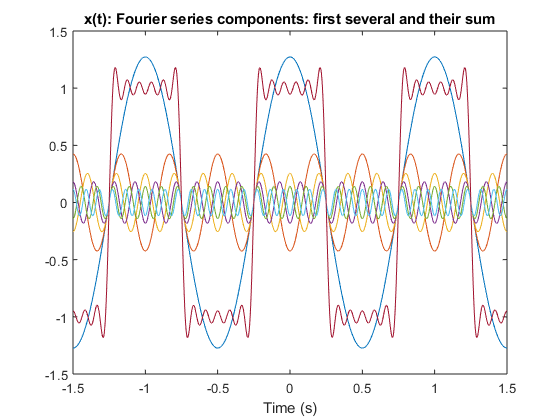

T0 = 1; % s, fundamental period
A = 1; % peak amplitude
k = [ 1  3    5   7   9     11]; % multipliers of the fundamental frequency
X = [1 -1/3 +1/5 -1/7 1/9 -1/11] * 2*A/pi; % we will learn how to derive this series given the square wave in week 7.
a = 2*real(X); % From derivation of trigonometric Fourier Series from exponential F.S.
a(k==0) = real(X(k==0)); % Fix the DC term, if any (k==0 can be the empty set)
assert(all(isreal(X)), 'Need to add b/sine components if X is not real')
 
omega = 2*pi*k/T0; % radians/s for each component. 1/T0 Hz, convert to radians, calculate frequency multiples/harmonics

t = linspace(-1.5, 1.5, 1000); % view a few cycles

x = zeros(size(t)); % initialize x(t) to be the correct size
for idx = 1:length(omega) % for each of the frequencies
   % This is the cosine part of the trigonometric form. Add sine if needed, or use exponential form.
   part = a(idx) * cos(omega(idx)*t); % calculate the contribution using the corresponding frequency component
   plot(t,part), hold on % plot that component, and "hold" previous plots as more are added
   x = x + part;
end

plot(t,x) % and plot the final signal
xlabel('Time (s)')
title('x(t): Fourier series components: first several and their sum')

## Week 6, Day 2

Try various h(t)/H(omega) functions. Try varying their parameters to cause the minimum change in shape to the input.

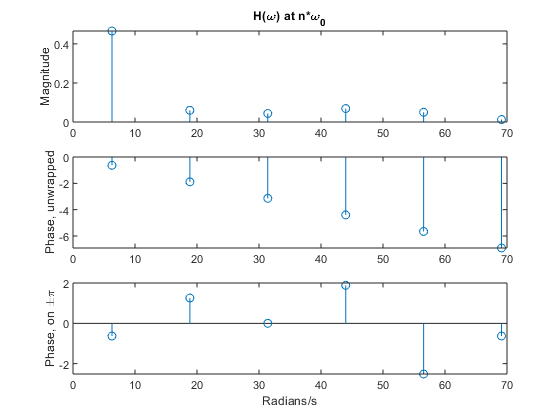

if false % h(t) = exp(-at)u(t)
    a = 10; % decay coefficient in h(t)
    H = 1 ./ (a + 1j * omega);
    analyticPhase = NaN(size(H)); % Could compute this, but it is not as simple as for the rectangular impulse response
elseif true % h(t) = (u(t) - u(t-TN)) * (1/TN) [area = 1]
    TN = 0.2;
    H = sinc(omega*TN/2).*exp(-1j*omega*TN/2);
    analyticPhase = -omega*TN/2;
else % h(t) = delta(t) [pass signal through]
    H = ones(size(omega));
    analyticPhase = zeros(size(omega));
end
subplot(3,1,1),stem(omega,abs(H)),ylabel('Magnitude')
title('H(\omega) at n*\omega_0')
subplot(3,1,2),stem(omega,analyticPhase),ylabel('Phase, unwrapped')
subplot(3,1,3),stem(omega,angle(H)),ylabel('Phase, on \pm\pi')
xlabel('Radians/s')

Now, build and plot y(t) using phasors Y = H X.

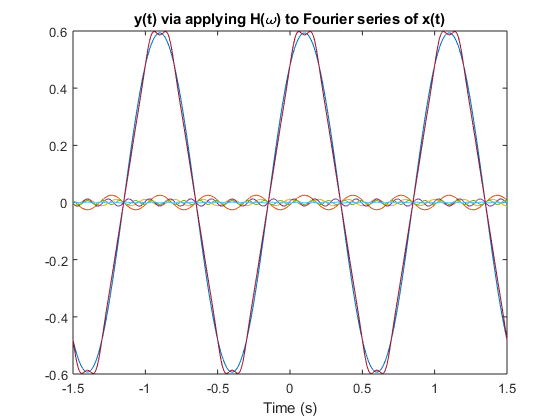

figure
y = zeros(size(t)); % initialize x(t) to be the correct size
for idx = 1:length(omega) % for each of the frequencies
   part = abs(2*X(idx))*abs(H(idx)) * cos (omega(idx)*t + ... % 2* since we're incorporating negative N through symmetry
       angle(X(idx)) +angle(H(idx)) ); % calculate the contribution using the corresponding X phasor
   plot(t,part), hold on % plot that component, and "hold" previous plots as more are added
   y = y + part;
end
plot(t,y), xlabel('Time (s)')
title('y(t) via applying H(\omega) to Fourier series of x(t)')

## Week 7, Day 4

## Line spectrum of X

% TODO

## Power of x(t), and Parseval's theorem

powerTheory = A^2; % For square wave with peak of A (not peak-peak)
dt = diff(t(1:2)); % time step for Riemann approximation
power = dt * sum(x(-T0/2<t&t<T0/2).^2)/T0; % take x over only 1 period; integral definition is average over time (T0)
powerParseval = NaN; % TODO
fprintf('Power of x(t):\n%g per theory\n%g via numeric integration\n%g per Parseval''s theorem, rel error = %g\n', ...
    powerTheory, power, powerParseval, (powerParseval-power)/power)

Power of x(t):
1 per theory
0.963609 via numeric integration
NaN per Parseval's theorem, rel error = NaN
